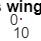

clc
clear all
syms GJ_root GJ_tip GJ b y w(y) t(Y) alpha alphae(y) M(y) Pdyn l(y) m(y) P(y) c(y) w(y) theta(y) b1 b2 b3 b4 b5 a1 a2 a3 a4 a5 y z
[Ma,Cla,Clac,Cmac,sweep,s,N,g,W,elevation,rho,T]=deal(0.8,6.28,5.05,-0.015,34*pi/180,21.33,3,9.81,66000,6000,0.54,251.7);
Pdyn=(sqrt(1.4*287*T)*Ma)^2/2*.54; %N/m^2
%LINEARLY VARYING TERMS
[EI(y),GJ(y),c(y),M(y),ec(y),x_cg(y)]=deal(4e8-.178e8*y,2.5e8-.109e8*y,5.285-.1442*y,800-28.13*y,.6875-0.0185*y,-0.106+.00288*y);
% no of terms
[n, m, w(y), theta(y)] = deal(5, 5, 0,0);
[a,b]=deal(sym('a',[1 n]),sym('b',[1 m]));

syms alpha
alphae(y)= alpha + theta(y)*cos(sweep)-diff(w(y),y)*sin(sweep);
syms l(y) m(y)
l(y)= Pdyn*Clac*c(y)*alphae(y);
P(y)= (l-N*M(y)*g)*cos(sweep);
m(y)=(l(y)*ec(y)+Pdyn*((c(y))^2)*Cmac-N*M(y)*g*x_cg(y))*(cos(sweep))^2;
D=EI(y)*diff(diff(w(y),y),y);
%residues
R1(y)=diff(diff(D,y),y)-P(y)-diff((l(y)*ec(y)+Pdyn*((c(y))^2)*Cmac-N*M(y)*g*x_cg(y)),y)*sin(sweep)*cos(sweep);
R2(y)=diff((GJ(y)*diff(theta(y),y)),y)+m(y);
% squaring residues
[Q1,Q2] = deal(R1(y)*R1(y),R2(y)*R2(y));
% integrating square of the residues
[I1,I2] = deal(int(Q1, 0, s),int(Q2, 0, s));
eq = cell(10,1);
% differentiating integrated square of the residues wrt coefficients
eq{1}=diff(I1 , a1);
eq{2}=diff(I1 , a2);
eq{3}=diff(I1 , a3);
eq{4}=diff(I1 , a4);
eq{5}=diff(I2 , b1);
eq{6}=diff(I2 , b2);
eq{7}=diff(I2 , b3);
eq{8}=diff(I2 , b4);
eq{9}=diff(I1 , a5);
eq{10}=diff(I2 , b5);
eq1=diff(I1 , a1);
eq2=diff(I1 , a2);
eq3=diff(I1 , a3);
eq4=diff(I1 , a4);
eq5=diff(I2 , b1);
eq6=diff(I2 , b2);
eq7=diff(I2 , b3);
eq8=diff(I2 , b4);
eq9=diff(I1 , a5);
eq10=diff(I2 , b5);
% divergence matrix
a= [a1;a2;a3;a4;b1;b2;b3;b4;a5;b5];
[a1, a2, a3, a4, b1, b2, b3, b4,a5,b5] = solve([eq1,eq2,eq3,eq4,eq5,eq6,eq7,eq8,eq9,eq10],[a1, a2, a3, a4, b1, b2, b3, b4,a5,b5]);
matrix = cell(10,1);
for i=1:10
 matrix{i} = fliplr(coeffs(eq{i},a));
end
%calculation of rigid angle of attack
L = vpa(2*int(l(y),[0,s]),10);
eqalpha = subs(L-N*W*g);
alpha = vpa(solve(eqalpha),10);
%-----------------------------------------------------------------------------------%
my(y)=(l(y)*ec(y)+Pdyn*((c(y))^2)*Cmac)*(cos(sweep))^2;
mx(y)=(l(y)*ec(y)+Pdyn*((c(y))^2)*Cmac)*sin(sweep)*cos(sweep);
%deflection
w(y)=vpa(subs(subs(w(y))),7);
%Twist
theta(y)=vpa(subs(subs(theta(y))),7);
%effective angle_of_attack
effectiveangle_of_attack(y)=subs(subs(alphae));
%lift
lift(y)= subs(subs(l(y)));
%slope
slope(y)=diff(w(y),y);
% moment
bendingmoment(y)=EI(y)*diff(slope(y),y);
%shear
shear(y)=diff(bendingmoment(y),y);
%torque
torque(y)=diff(GJ(y)*theta(y),y);
%Running torsional momemt
running_torsional_moment(y)=subs(subs(my(y)));
%Running Bending momemt
running_bending_moment(y)=subs(subs(mx(y)));
figure;
fplot(w(y),[0,21.33],'r')
grid on;
hold on
title('deflection vs wing coordinates');xlabel('position on wing in (metre) from the root');ylabel('deflection w (m)');

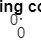

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
fplot(theta(y),[0,21.33],'r')
grid on;hold on
title('twist vs wing coordinates');xlabel('position on wing in (metre) from the root');ylabel('twist w (radian)');

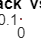

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
fplot(effectiveangle_of_attack(y),[0,21.33],'r')
grid on;hold on;ylim([0 .2])
title('effective angle_of_attack vs wing coordinates');xlabel('position on wing in (metre) from the root');
ylabel('effective angle_of_attack in radian');

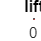

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
fplot(lift(y),[0,21.33],'r')
grid on;hold on; ylim([0 8*10^4])
title('lift');xlabel('position on wing in (metre) from the root');ylabel('lift(N/m)');

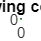

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
fplot(slope(y),[0,21.33],'g')
grid on;hold on
title('slope vs wing coordinates');xlabel('position on wing in (metre) from the root');ylabel('slope in radian');

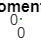

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
fplot(bendingmoment(y),[0,21.33],'g')
grid on;hold on
title('Sectional Bending moment vs wing coordinates');xlabel('position on wing in (metre) from the root');
ylabel('moment in (Nm/m)');

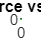

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
fplot(shear(y),[0,21.33],'g')
grid on;hold on
title('Sectional shear force vs wing coordinates');xlabel('position on wing in (metre) from the root');
ylabel('Sectional shear force in (N/m)');

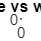

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
fplot(torque(y),[0,21.33],'g')
grid on;hold on
title('Sectional Torque vs wing coordinates');xlabel('position on wing in (metre) from the root');
ylabel('Sectional Torque in (Nm/m)');

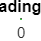

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
fplot(running_torsional_moment(y),[0,21.33],'g')
grid on;hold on
title('Torsional moment loading vs wing coordinates');xlabel('position on wing in (metre) from the root');
ylabel('Torsional moment loading in (Nm/m)');

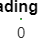

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
fplot(running_bending_moment,[0,21.33],'g')
grid on;hold on
title('Bending moment loading vs wing coordinates');xlabel('position on wing in (metre) from the root');
ylabel('Bending moment loading in (Nm/m)');

fprintf('\n rigid angle of attack = %0.4f radian', alpha);


 rigid angle of attack = 0.1377 radian